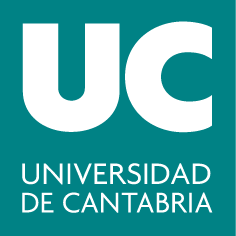

***Grado de Tecnologías de Telecomunicación***

**G282: Álgebra y Geometria**

# **Práctica 3: Sistemas de ecuaciones lineales**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Objetivos**

- Resolución de sistemas compatibles determinados (no homogéneos)

- Resolución de sistemas compatibles indeterminados (no homogéneos)

- Resolución de sistemas homogéneos

## **Forma escalonada reducida y rango**

Sea la matriz $A$ =$\left\lbrack \begin{array}{cccc}
-2 & 0 & 0 & 0\\
1 & 0 & 0 & 0\\
2 & 0 & -1 & 2\\
5 & 0 & 1 & 2
\end{array}\right\rbrack$

A = [-2 0 0 0; 1 0 0 0; 2 0 -1 2; 5 0 1 2];  % defino la matriz A

El comando *rref *permite encontrar la forma escalonada reducida (por filas) directamente:

Ared = rref(A)  % Ared es la forma reducida por filas 

*rref *admite un segundo argumento de salida que nos devuelve un índice que identifica a las columnas pivotales:

[Ared, cp] = rref(A)  % cp es un vector que contiene los índices que 
% identifican las columnas pivotales

Por tanto, el rango de la matriz puede ser fácilmente obtenido a partir de este vector de índices:

length(cp)  % rango = número de columnas pivotales
rank(A)  % comprobación

## **Resolución de sistemas compatibles determinados (no homogéneos)**

Siempre que estemos frente a un sistema de ecuaciones lineales, lo primero que haremos es clasificarlo (si es incompatible, no habrá nada más que hacer). Para ello, partiendo de la matriz de coeficientes y la matriz ampliada del sistema, aplicaremos el teorema de Rouché-Fröbenius. Vamos a verlo con el siguiente ejemplo:


$$\textstyle\left\{  \begin{array}{rcr}
			 x  + y - z & = & 0\\ 
			 3x + y -z & = & 2\\
			 4x - 2y + z & = & 3\\  
		 \end{array}\right.$$


% clasifico el sistema
A = [1 1 -1; 3 1 -1; 4 -2 1]; % matriz de coeficientes
b = [0 2 3]';  % vector de términos independienets
Aamp = [A, b];  % matriz ampliada
[rank(A), rank(Aamp)]  % R-F: sistema compatible determinado

Una vez hemos comprobado que el sistema es compatible determinado (habrá una única solución), veremos a continuación distintas formas de resolver este tipo de sistemas:

Método 1: Si existe, utilizar la matriz $A^{-1}$ para despejar el vector de incógnitas $\vec{x}$ en la ecuación matricial del sistema, $A\vec{x}=\vec{b}$

inv(A)*b  % solución: (x=1, y=2, z=3)

Método 2: Calcular la forma escalonada reducida por filas de la matriz ampliada del sistema (método de Gauss-Jordan).

rref(Aamp)  % solución: (x=1, y=2, z=3)

Método 3: Con la función *linsolve*. Requiere como entradas la matriz de coeficientes y el vector de términos independientes. **¡Cuidado! **Proporciona solución a Sistemas Incompatibles (la "solución" que más se aproxima) y devuelve una sola solución para Sistemas Compatibles Indeterminados

linsolve(A, b)  % solución: (x=1, y=2, z=3)

Método 4: Con el operador "\" (comando *mldivide*). Al igual que para *linsolve,* necesitaremos la matriz de coeficientes y el vector de términos independientes. **¡Cuidado! **Proporciona solución a Sistemas Incompatibles (la "solución" que más se aproxima) y devuelve una sola solución para Sistemas Compatibles Indeterminados

A\b  % solución: (x=1, y=2, z=3)

Siempre es **altamente recomendable **comprobar que esa solución a la que hemos llegado es correcta, es decir, que cumple todas las ecuaciones del sistema simultáneamente (satisface su ecuación matricial).

sol = A\b;
A*sol - b  % comprobación: A*sol = b

## **Resolución de sistemas compatibles indeterminados (no homogéneos)**

En el caso de sistemas compatibles indeterminados (infinitas soluciones) **no se deben** emplear los métodos vistos anteriormente. Vamos a ilustrar cómo se pueden resolver este tipo de sistemas con el siguiente ejemplo:


$$\textstyle\left\{  \begin{array}{rcr}
			 x  + y + z + t & = & 7\\ 
			 x + y + 2t & = & 8\\
			 2x + 2y + 3z & = & 10\\  
			 -x - y - 2z + 2t & = & 0
\\  
		 \end{array}\right.$$


Como siempre, lo primero que haremos es clasificar el sistema haciendo uso del comando *rank *y el teorema de Rouché-Fröbenius.

% clasifico el sistema
A = [1 1 1 1; 1 1 0 2; 2 2 3 0; -1 -1 -2 2]; % matriz de coeficientes
b = [7 8 10 0]';  % vector de términos independienets
Aamp = [A, b];  % matriz ampliada
[rank(A), rank(Aamp)]  % R-F: sistema compatible indeterminado

A continuación, calcularemos la escalonada reducida por filas de la matriz ampliada.  En la parte correspondiente a la matriz de coeficientes podremos identificar las incógnitas principales (columnas pivotales) y los parámetros libres (columnas no pivotales). Recuerda que el nº de parámetros libres será igual al nº total de incógnitas menos el nº de incógnitas principales.

rref(Aamp)  % escalonada reducida por filas
% incógnitas principales: {x, z, t}
% parámetro libre: {y}

Una vez hemos determinado cuáles vamos a considerar como incógnitas principales, resolvemos el sistema utilizando el procedimiento visto en clase. La solución dependerá de uno o varios parámetros libres. 

Puedes sustituir en la solución general el parámetro libre por cualquier valor y comprobar que, efectivamente, se cumplen todas las ecuaciones del sistema.

## **Resolución de sistemas homogéneos**

Como sabes, los sistemas homogéneos siempre son compatibles, pudiendo tener solución única (la trivial) o infinitas soluciones. Comencemos con un sistema homogéneo determinado como el siguiente:


$$\textstyle\left\{  \begin{array}{rcr}
			 x - 3y + 4z & = & 0\\ 
			 x - 2y + 5z & = & 0\\
			 2x - y - 3z & = & 0\\  
		 \end{array}\right.$$


A = [1 -3 4; 1 -2 5; 2 -1 -3]; b = zeros(3,1); rank(A)  % R-F: S.C.D.

Por tener solución única, podríamos resolverlo utilizando cualquiera de los métodos 1-4 que vimos en la práctica anterior (aunque sabemos de antemano que la solución será $x=y=z=0$):

%% Método 1 (usado A^-1)
inv(A)*b  % solución: (x=0, y=0, z=0)
%% Método 2 (escalonada reducida)
rref(A)  % solución: (x=0, y=0, z=0)
%% Método 3 ("linsolve")
linsolve(A, b)  % solución: (x=0, y=0, z=0)
%% Método 4 ("\")
A\b  % solución: (x=0, y=0, z=0) 

Pasemos ahora al caso de sistemas homogéneos indeterminados (con infinitas soluciones), como el que se muestra a continuación:


$$\textstyle\left\{  \begin{array}{rcr}
			 2x + y + z & = & 0\\ 
			 3x - z & = & 0\\
			 10x + 5y + 5z & = & 0\\  
		 \end{array}\right.$$


A = [2 1 1; 3 0 -1; 10 5 5];  % matriz de coeficientes
b = zeros(3,1);  % términos indep.
rank(A)  % R-F: S.C.I.

Tal y como vimos en el apartado anterior, podemos utilizar el comando *rref* para resolver este tipo de sistemas:

rref(A)  % escalonada reducida por filas --> I.P: {x,y}, P.L.: {z}

Sin embargo, MATLAB cuenta con un comando específico para resolver directamente sistemas homogéneos (ya sean determinados o indeterminados): *null. *Este comando es muy útil (sólo requiere como entrada la matriz de coeficientes del sistema, $A$), pero hay que saber cómo interpretar el resultado que devuelve. En el caso de sistemas homogéneos determinados como el que utilizamos en el primer ejemplo de este apartado, *null* devolverá una matriz vacía, lo que indica que la única solución del sistema es la trivial.


$$\textstyle\left\{  \begin{array}{rcr}
			 x - 3y + 4z & = & 0\\ 
			 x - 2y + 5z & = & 0\\
			 2x - y - 3z & = & 0\\  
		 \end{array}\right.$$


A = [1 -3 4; 1 -2 5; 2 -1 -3];  % matriz de coeficientes
null(A, 'r')  % sol. trivial: (x=0, y=0, z=0)

***Nota****: En el comando null, el argumento de entrada "r" es opcional. Sin embargo, nosotros vamos a usarlo siempre, pues da lugar a los mismo números racionales que se obtendrían con rref, que resultan más manejables. *

En el caso de sistemas homogéneos indeterminados como el que hemos utilizado como segundo ejemplo en ese apartado, la solución vendrá dada por la combinación lineal de las columnas de la matriz que devuelve *null. *


$$\textstyle\left\{  \begin{array}{rcr}
			 2x + y + z & = & 0\\ 
			 3x - z & = & 0\\
			 10x + 5y + 5z & = & 0\\  
		 \end{array}\right.$$


A = [2 1 1; 3 0 -1; 10 5 5];  % matriz de coeficientes
solh = null(A, 'r')

En este caso, *null* devuelve una única columna, por lo que la solución del sistema será $\alpha \left(\frac{1}{3}, -\frac{5}{3},1 \right)$*, *siendo $\alpha \in \mathbb{R}$ un parámetro libre*. *Comprobemos para un valor cualquiera de $\alpha$ que la solución hallada es correcta:

format rat
solh
format short
alpha = -6.78;  % doy un valor cualquiera al P.L.
sol = alpha*solh;  % solución 
A*sol  % comprobación

Veamos otro sistema homogéneo indeterminado en cuyas soluciones intervengan más parámetros libres, como por ejemplo este:


$$\textstyle\left\{  \begin{array}{rcr}
			 4x + 5y + 6z & = & 0\\ 
			 8x + 10y + 12z & = & 0\\
		 \end{array}\right.$$


A = [4 5 6; 8 10 12];
rank(A)  % R-F: S.C.I.
solh = null(A, 'r')  % la sol. del sistema dependerá de dos P.L.

En este caso, la solución será $\alpha\left(-\frac{5}{4},1,0\right) + \beta\left(-\frac{3}{2},0,1\right)$. Comprobémoslo:

alpha = -1.23; beta = pi/6;  % doy valores cualesquiera a los P.L.
sol = alpha*solh(:,1) + beta*solh(:,2)
A*sol  % comprobación

## Ejercicios propuestos

**Ejercicio 1:**

Comprueba que el siguiente sistema es compatible determinado y resuélvelo utilizando los métodos 1-4 que hemos visto para este tipo de sistemas. Verifica que la solución que has obtenido es la correcta.


$$\textstyle\left\{  \begin{array}{rcr}
			 -x -2y - 3z & = & -3\\ 
			 2x + 3y + 2z & = & -2\\
			 x + 2y + 4z & = & 
3\\  
		 \end{array}\right.$$


**Ejercicio 2:**

Clasifica los siguientes sistemas

*a)*$\left\lbrack \begin{array}{ccccc}
-5 & 10 & 11 & 10 & -67\\
2 & -4 & 5 & 12 & 47\\
-1 & 2 & 21 & 34 & 27
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x\\
y\\
z\\
t\\
p
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$          *b)*$\left\lbrack \begin{array}{ccc}
-5 & -7 & 11\\
9 & -4 & 5\\
-1 & 5 & 21
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$      

**Ejercicio 3:**

Obtén la solución general del siguiente sistema:


$$$ \textstyle\left\{ \begin{array}{rcr} -x +2y-z+4t+5p & = & 0\\ -2x +3y-10z-14t & = & 0 \\ 3x -2y+4z+14t+6p & = & 0 \\ -6x +4y-8z-28t-12p & = & 0 \\ -3x +2y-4z-14t-6p & = & 0 \\\end{array}\right.$$$


**Solución 1:**

Comprueba que el siguiente sistema es compatible determinado y resuélvelo utilizando los métodos 1-4 que hemos visto para este tipo de sistemas. Verifica que la solución que has obtenido es la correcta.


$$\textstyle\left\{  \begin{array}{rcr}
			 -x -2y - 3z & = & -3\\ 
			 2x + 3y + 2z & = & -2\\
			 x + 2y + 4z & = & 
3\\  
		 \end{array}\right.$$


% clasifico el sistema
A = [-1 -2 -3; 2 3 2; 1 2 4];  % matriz de coeficientes
b = [-3 -2 3]';  % vector de términos independientes
Aamp = [A, b];  % matriz ampliada
[rank(A), rank(Aamp)]  % R-F: sistema compatible determinado

Método 1:

inv(A)*b  % solución: (x=-13, y=8, z=0)

Método 2:

rref(Aamp)  % solución: (x=-13, y=8, z=0)

Método 3:

linsolve(A, b)  % solución: (x=-13, y=8, z=0)

Método 4:

A\b  % solución: (x=-13, y=8, z=0)

**Solución 2:**

Resuelve los siguientes sistemas:

*a)*$\left\lbrack \begin{array}{ccccc}
-5 & 10 & 11 & 10 & -67\\
2 & -4 & 5 & 12 & 47\\
-1 & 2 & 21 & 34 & 27
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x\\
y\\
z\\
t\\
p
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$          *b)*$\left\lbrack \begin{array}{ccc}
-5 & -7 & 0\\
9 & -4 & 5\\
-1 & 5 & 21
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$      

%% a)
A = [-5 10 11 10 -67; 2 -4 5 12 47; -1 2 21 34 27]; b = zeros(3,1);
rank(A)  % R-F: S.C.I.
% Opción 1: con el comando "null"
solh = null(A, 'r')  % habrá tres P.L. en la sol. general

%% b)
A = [-5 -7 0; 9 -4 5; -1 5 21];  % matriz de coefs.
rank(A)  % R-F: S.C.D. --> sol. trivial
A\zeros(3,1)  % comprobación 1
null(A, 'r')  % comprobación 2

**Solución 3:**

Obtén la solución general del siguiente sistema:


$$$ \textstyle\left\{ \begin{array}{rcr} -x +2y-z+4t+5p & = & 0\\ -2x +3y-10z-14t & = & 0 \\ 3x -2y+4z+14t+6p & = & 0 \\ -6x +4y-8z-28t-12p & = & 0 \\ -3x +2y-4z-14t-6p & = & 0 \\\end{array}\right.$$$


A = [-1 2 -1 4 5; -2 3 -10 -14 0; 3 -2 4 14 6; -6 4 -8 -28 -12; -3 2 -4 -14 -6];
rank(A)  % R-F: S.C.I.

solh = null(A, 'r')  % habrá dos P.L. en la sol. general